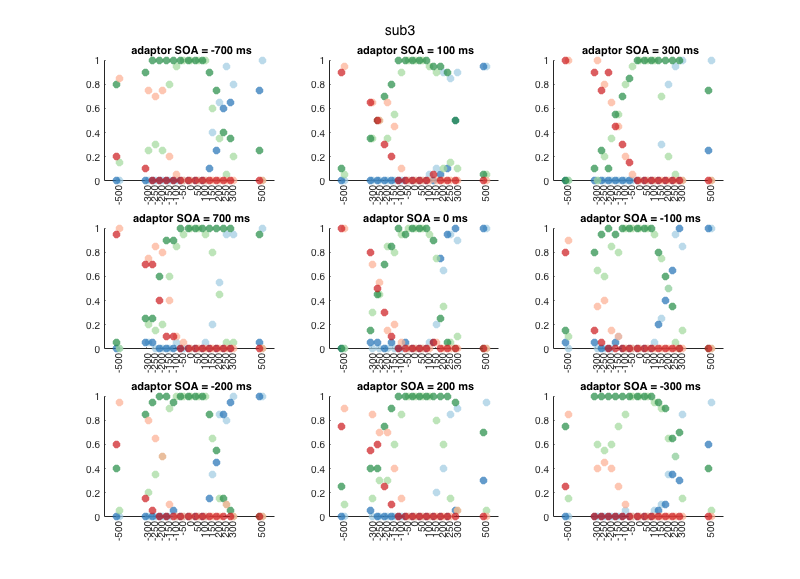

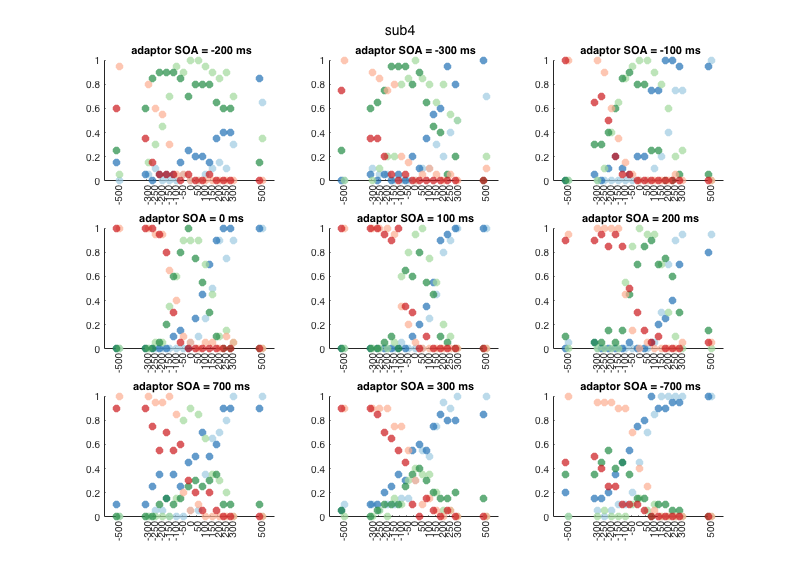

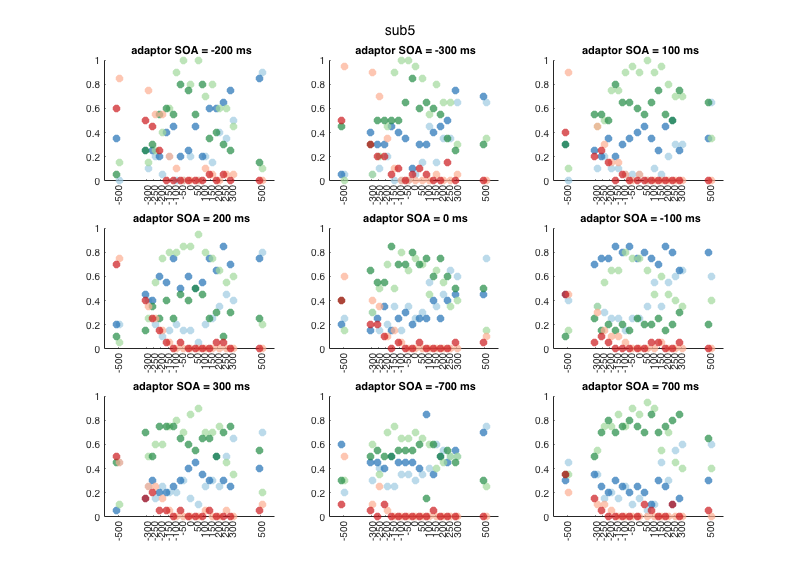

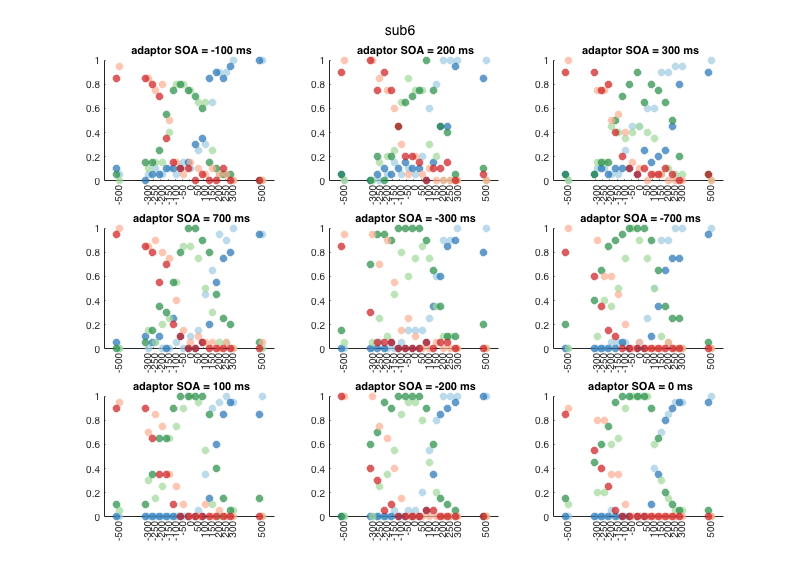

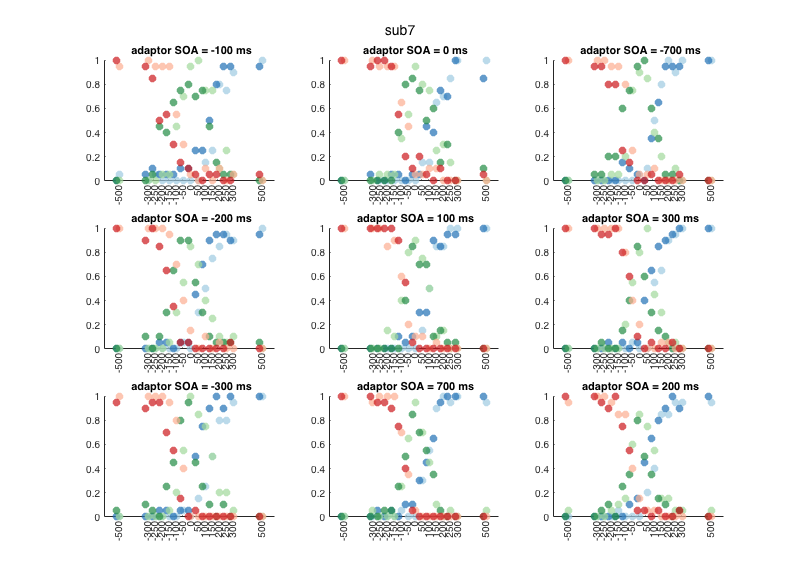

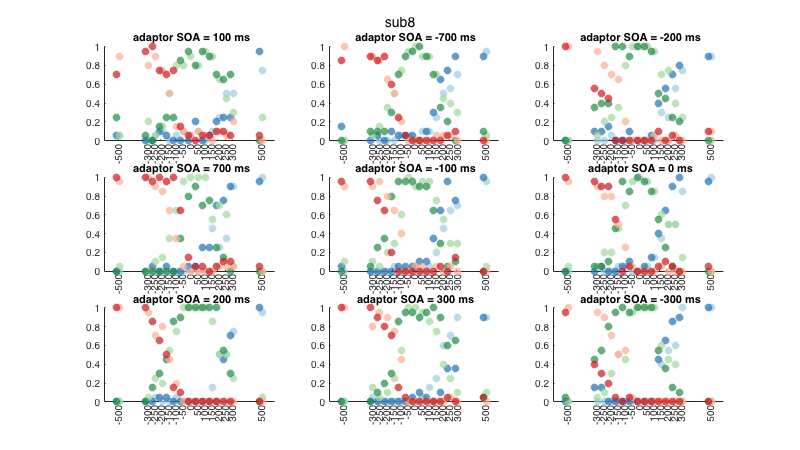

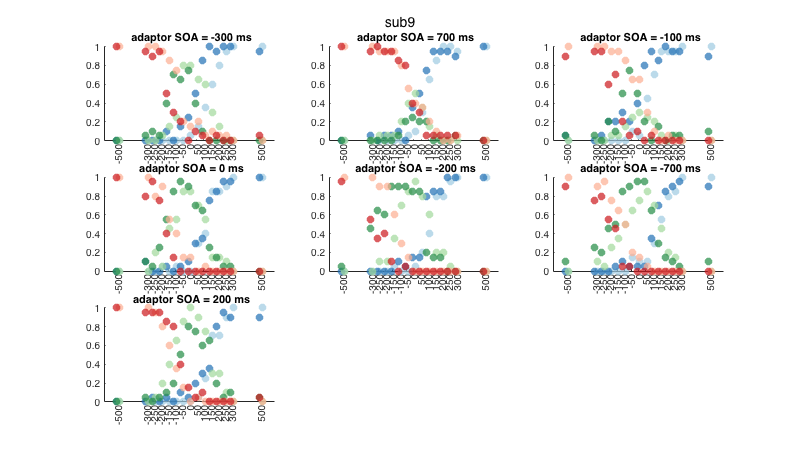

% This script plots the raw responses for the ternary TOJ task, for each
% subject. Lighter colors jittered to the right indicate pre-test data and
% darker colors jittered to the left indicate post-test data.

clear all; close all; clc;
for subjID = 1:10
    figure; hold on
    set(gca, 'FontSize', 20, 'LineWidth', 1.5); box off
    set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0, 1, 1]);
    for sess = 1:9
        % check if file exist
        if exist(['pretest_sub' num2str(subjID) '_session' num2str(sess) '.mat']) == 0 % skip if the file does not exist
        else
        %% organize data
        %% %%% pre-test
        load(['pretest_sub' num2str(subjID) '_session' num2str(sess) '.mat'])
        pre_s_unique = ExpInfo.SOA; % unique SOA levels, in ms
        pre_numTrials = ExpInfo.nTrials; % num of trials per SOA
        % inititate
        pre_r_org = NaN(length(pre_s_unique), pre_numTrials);
        pre_respCount = NaN(3, length(pre_s_unique));
        for i = 1:length(pre_s_unique)
            iSOA = pre_s_unique(i);
            iResp = Response.order(ExpInfo.trialSOA == iSOA);
            pre_r_org(i,:) = iResp; % this matrix has a size of length(s_unique) x numTrials
            for j = unique(Response.order) % 1 = V first, 2 = simultaneous, 3 = A first
                pre_respCount(j,i) = sum(iResp == j);
            end
        end
        pre_pResp = pre_respCount/pre_numTrials;

        %% %%% post-test
        load(['posttest_sub' num2str(subjID) '_session' num2str(sess) '.mat'])
        post_s_unique = ExpInfo.SOA; % unique SOA levels, in ms
        post_numTrials = ExpInfo.nTrials; % num of trials per SOA
        % inititate
        post_r_org = NaN(length(post_s_unique), post_numTrials);
        post_respCount = NaN(3, length(post_s_unique));
        for i = 1:length(post_s_unique)
            iSOA = post_s_unique(i);
            iResp = Response.order(ExpInfo.trialSOA == iSOA);
            post_r_org(i,:) = iResp; % this matrix has a size of length(s_unique) x numTrials
            for j = unique(Response.order) % 1 = V first, 2 = simultaneous, 3 = A first
                post_respCount(j,i) = sum(iResp == j);
            end
        end
        post_pResp = post_respCount/post_numTrials;

        %% plot
        subplot(3,3,sess); hold on

        cMAP1 = [158,202,225; 161,217,155; 252,174,145]./255;
        cMAP2 = [33,113,181; 35,139,69; 203,24,29]./255;
        alpha = 0.7;

        % pre-data
        for i = 1:3
            scatter(pre_s_unique*1000+10, pre_pResp(i,:),60,'MarkerFaceColor', cMAP1(i,:),...
                'MarkerEdgeAlpha', 0, 'MarkerFaceAlpha',alpha)
            scatter(post_s_unique*1000-10, post_pResp(i,:),60,'MarkerFaceColor', cMAP2(i,:),...
                'MarkerEdgeAlpha', 0, 'MarkerFaceAlpha',alpha)
        end
        xticks(pre_s_unique*1000)
        xlim([-600 600])
        sgtitle(['sub' num2str(subjID)])
        title([' adaptor SOA = ' num2str(ExpInfo.adaptor*1000) ' ms'])
        
        end

    end
end